قسمت اول

% 810101361
% Aij--->N(1,0.6)----->(100,1000)
% Xij--->N(3,0.1)----->(1000,1)
% Nij--->N(0,1)----->(100,1)

%each time we Run the code we have same matrixes
s=rng; 
% Generate random matrices A, X, and N
A = 1 + sqrt(0.6)*randn(100,1000);
X = 3 + sqrt(0.1)*randn(1000,1);
N = randn(100,1);
rng(s);

% Compute Y
Y = A * X + N;

% Use least squares to estimate A
A_hat=Y*pinv(X);

% Compute the error between A and A_hat
ErrEstimate = norm(A-A_hat,2)/norm(A,2);

% Display the error
disp(['Error between A and A_hat (Error of the estimation): ', num2str(ErrEstimate)]);

Error between A and A_hat (Error of the estimation): 0.13276


%CRLB
sigma2 = var(N);
CRLB = sigma2*(inv(X.'*X))

CRLB = 1.0471e-04



sigma2=1;
CRLB=sigma2*inv(X.'*X)

CRLB = 1.0935e-04

y_hat=A_hat*X;
var(Y-y_hat)%deghat takhmin

ans = 4.2913e-25

var(N)%%variance noise

ans = 0.9576

var(A_hat(:,1))

ans = 5.9448e-04

var(A_hat(:,2))

ans = 5.7517e-04

var(A_hat(:,3))

ans = 5.9110e-04

var(A_hat(:,4))

ans = 7.9896e-04

var(A_hat(:,5))

ans = 7.5991e-04

قسمت دوم

num_repeats = 100;
errors = zeros(num_repeats, 1);
for i = 1:num_repeats
    A1 = 1 + sqrt(0.6)*randn(100,1000);
    X1 = 3 + sqrt(0.1)*randn(1000,1);
    % Generate new random noise
    N2 = randn(100,1);
    % Recompute Y
    Y1 = A1*X1 + N2;
    % Recompute X_ls and error
    A_hat1 = Y1*pinv(X1);
    errors(i) = norm(A1 - A_hat1)/norm(A1);
end

q=cov(N)*eye(10);

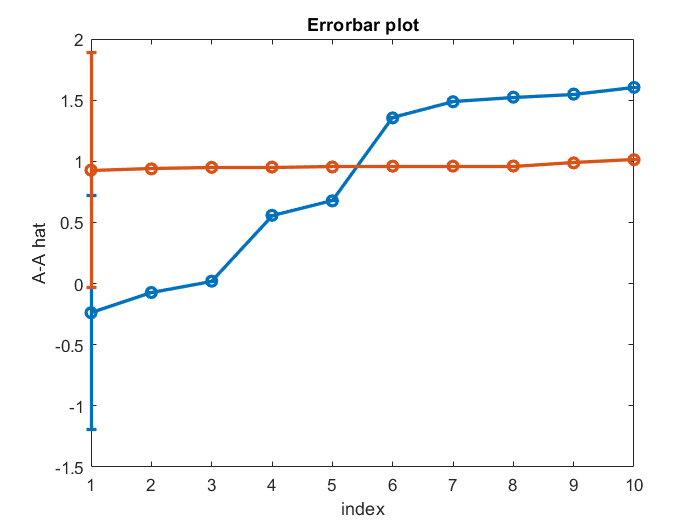

errorbar(sort(A(1:10,1)), q(1:10,1), 'o-', 'LineWidth', 2);
hold on
errorbar(sort(A_hat(1:10,1)), q(1:10,1), 'o-', 'LineWidth', 2);
xlabel('index');
ylabel('A-A hat');
title('Errorbar plot');
hold off

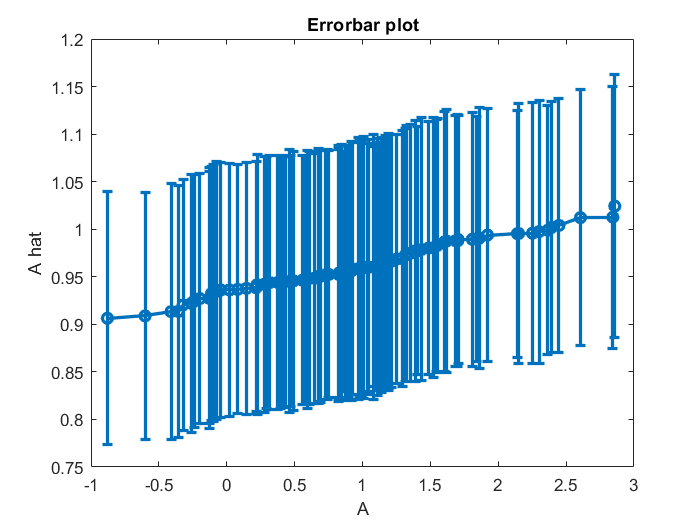

errorbar(sort(A(1:100,1)), sort(A_hat(1:100,1)), errors(1:100,1), 'o-', 'LineWidth', 2);
xlabel('A');
ylabel('A hat');
title('Errorbar plot');

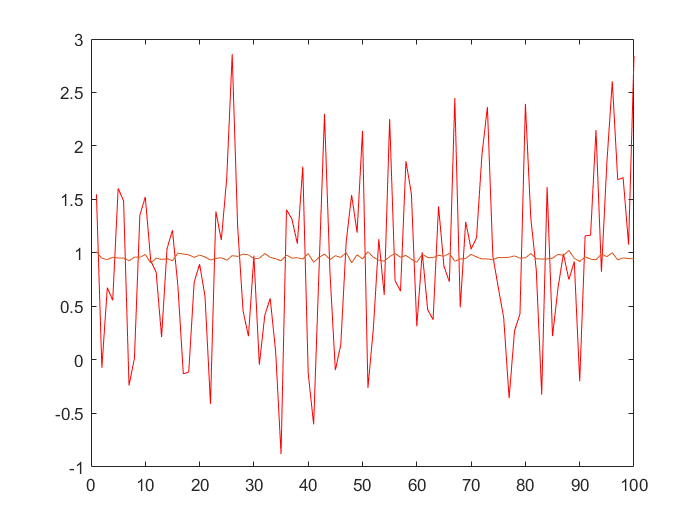

plot(A(1:100,1),'r')
hold on
plot(A_hat(1:100,1))
hold off

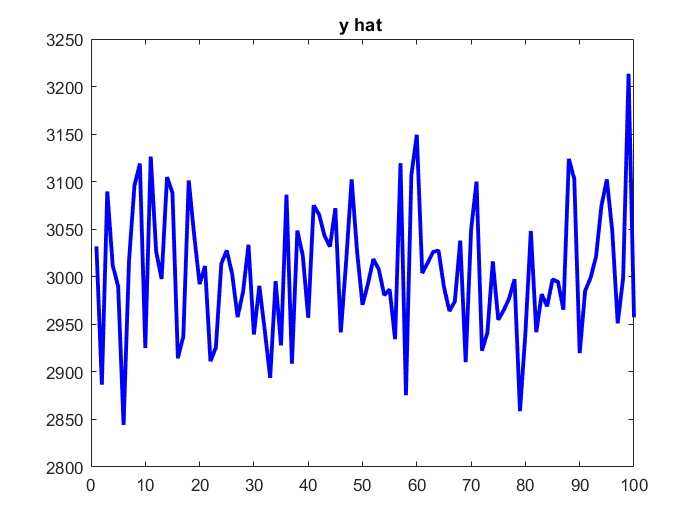

y_hat=A_hat*X;

figure;
plot(y_hat,'b','linewidth',2.3);
title("y hat ");

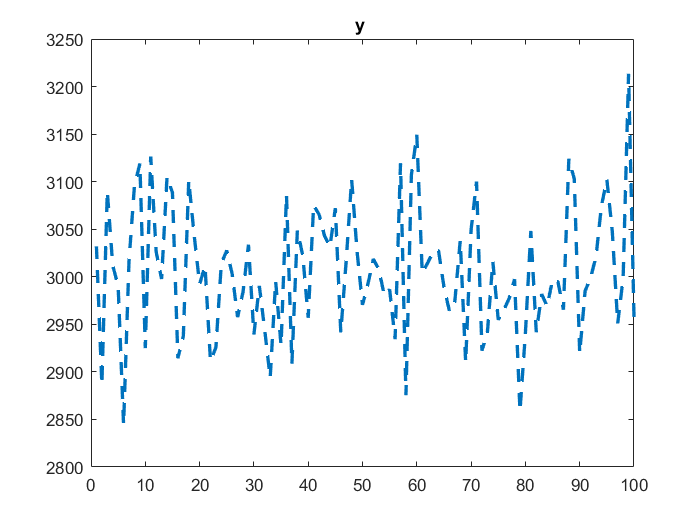


plot(Y,'--','linewidth',2);
title("y ");

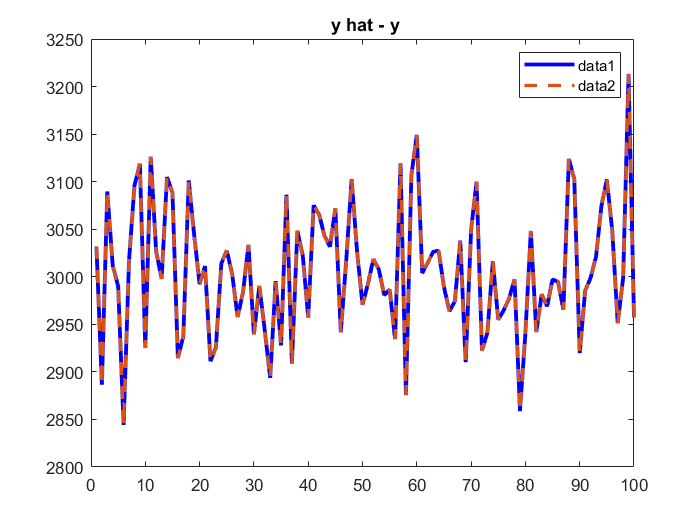

y_hat=A_hat*X;

figure;
plot(y_hat,'b','linewidth',2.3);

hold on
plot(Y,'--','linewidth',2);
title(" y hat - y");

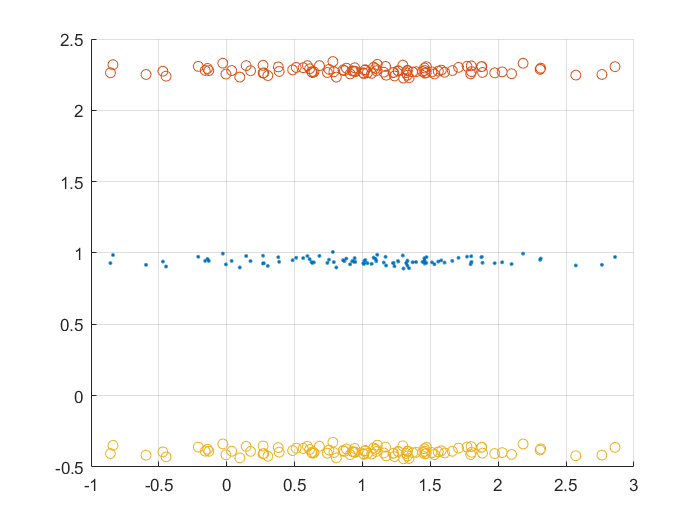

cov_a_hat=((errors'*errors)*(X'*X)^-1);
errorbar1=sqrt(diag(norm(X*cov_a_hat*X')));
figure;
scatter(A(1:100,2),A_hat(1:100,2),'.');
hold on
scatter(A(1:100,2),A_hat(1:100,2)+errorbar1);
hold on
scatter(A(1:100,2),A_hat(1:100,2)-errorbar1);
grid 

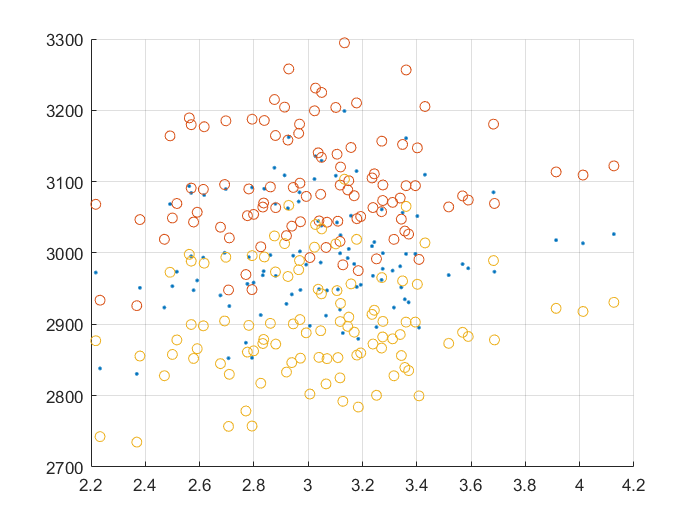

u=X(1:100,1);
error = Y - y_hat;
cov_A_hat=((errors'*errors)*(X'*X)^-1)/100-1;
errorbar1=sqrt(diag(norm(X*cov_A_hat*X')));
figure;
scatter(u,y_hat,'.');
hold on
scatter(u,y_hat+errorbar1);
hold on
scatter(u,y_hat-errorbar1);
grid

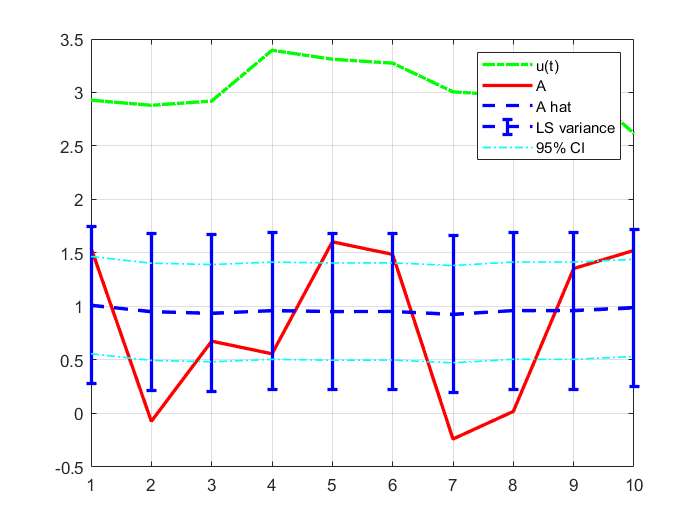

% Calculate the error and its standard deviation
e_noise = A(1:10,1) - A_hat(1:10,1);
err_noise = std(e_noise) .* ones(size(e_noise));

% Calculate the confidence interval
CI = 1.96 * std(e_noise) / sqrt(length(e_noise));
CI_low = A_hat(1:10,1) - CI;
CI_high = A_hat(1:10,1) + CI;

% Plot 
figure
plot(u(1:10,1), '-.g', 'LineWidth', 2)
hold on
plot(A(1:10,1), '-r', 'LineWidth', 2)
plot(A_hat(1:10,1), '--b', 'LineWidth', 2)
errorbar(A_hat(1:10,1), err_noise, '--b', 'Linewidth', 2, 'Markersize', 10)
plot(CI_low, '-.c', 'LineWidth', 1)
plot(CI_high, '-.c', 'LineWidth', 1)
grid
legend('u(t)', 'A', 'A hat', 'LS variance', '95% CI')

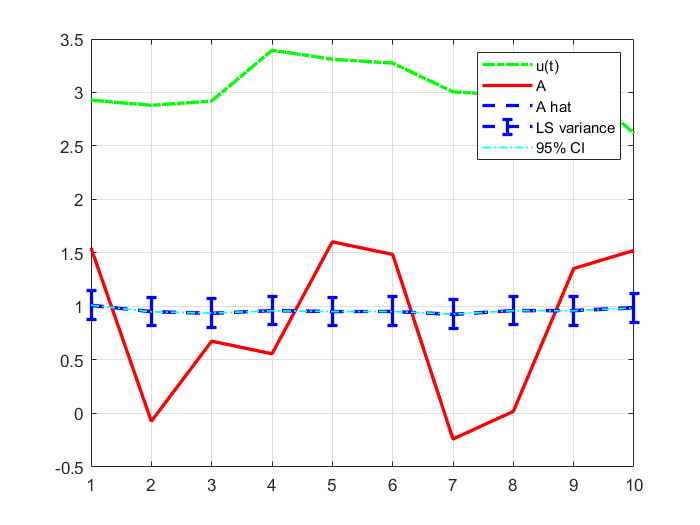

err_noise = std(errors) .* ones(size(errors));

% Calculate the confidence interval
CI = 1.96 * std(errors) / sqrt(length(errors));
CI_low = A_hat(1:10,1) - CI;
CI_high = A_hat(1:10,1) + CI;

% Plot 
figure
plot(u(1:10,1), '-.g', 'LineWidth', 2)
hold on
plot(A(1:10,1), '-r', 'LineWidth', 2)
plot(A_hat(1:10,1), '--b', 'LineWidth', 2)
errorbar(A_hat(1:10,1), errors(1:10,1), '--b', 'Linewidth', 2, 'Markersize', 10)
plot(CI_low, '-.c', 'LineWidth', 1)
plot(CI_high, '-.c', 'LineWidth', 1)
grid
legend('u(t)', 'A', 'A hat', 'LS variance', '95% CI')

mean_error = mean(abs(e_noise))
var_error = var((e_noise))

mean_error = mean(abs(errors))

mean_error = 0.1335

var_error = var((errors))

var_error = 9.6524e-06

hold off

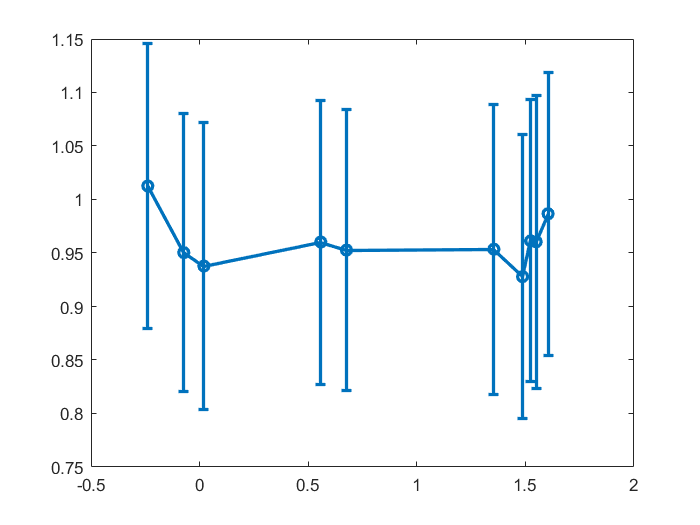

errorbar(sort(A(1:10,1)), A_hat(1:10,1), errors(1:10,1), 'o-', 'LineWidth', 2);

figure
plot(sort(A(1:100,3)), '-r','LineWidth',5)
hold on
plot(sort(A_hat(1:100,3)), '--g','LineWidth',5)
hold on
errorbar(sort(A_hat(1:100,3)),errors ,'--b','Linewidth',1,'Markersize',10)
grid
title('error bar')
legend( 'A', 'A hat', 'LS variance')
hold off

















% % Calculate the error and its standard deviation
% e_noise = A(1:10,1) - A_hat(1:10,1);
% err_noise = std(e_noise) .* ones(size(e_noise));
% 
% % Calculate the confidence interval
% CI = 1.96 * std(e_noise) / sqrt(length(e_noise));
% CI_low = A_hat(1:10,1) - CI;
% CI_high = A_hat(1:10,1) + CI;
% data = [A_hat(1:100,2)-errorbar1;  A_hat(1:100,2) ; A_hat(1:100,2)+errorbar1].';
% x = 1:300;
% 
% % Plot 
% figure
% plot(u(1:10,1), '-.g', 'LineWidth', 2)
% hold on
% plot(A(1:10,1), '-r', 'LineWidth', 2)
% plot(A_hat(1:10,1), '--b', 'LineWidth', 2)
% errorbar(A_hat(1:10,1), err_noise, '--b', 'Linewidth', 2, 'Markersize', 10)
% plot(CI_low, '-.c', 'LineWidth', 1)
% plot(CI_high, '-.c', 'LineWidth', 1)
% grid
% legend('u(t)', 'A', 'A hat', 'LS variance', '95% CI')
% hold on;
% boxplot(data, 'positions', x, 'widths', 0.2);
% hold off;



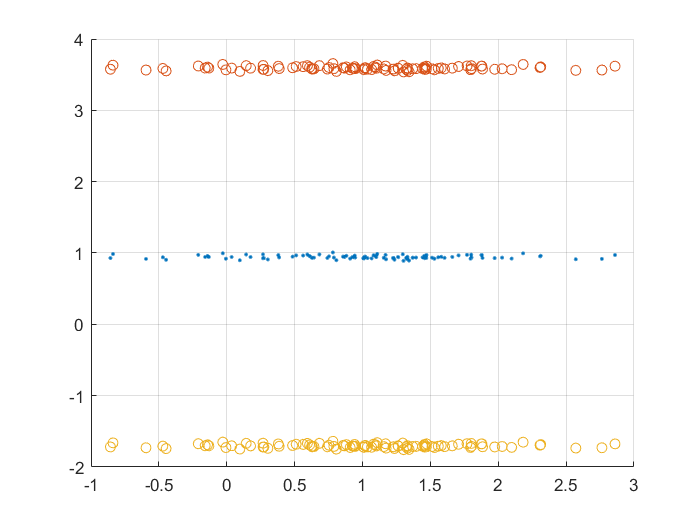


sigma2=(errors'*errors)/(100-1);
CRLB=sigma2*(X'*X)^-1;
cov_teta_hat=((errors'*errors)*(X'*X)^-1);
se = sqrt(diag(norm(X*cov_teta_hat*X')));
t_value = tinv(0.975, 100-1); %confidence interval 
c = t_value*se;
figure;
scatter(A(1:100,2),A_hat(1:100,2),'.');
hold on
scatter(A(1:100,2),A_hat(1:100,2)+c);
hold on
scatter(A(1:100,2),A_hat(1:100,2)-c);
grid 
hold off

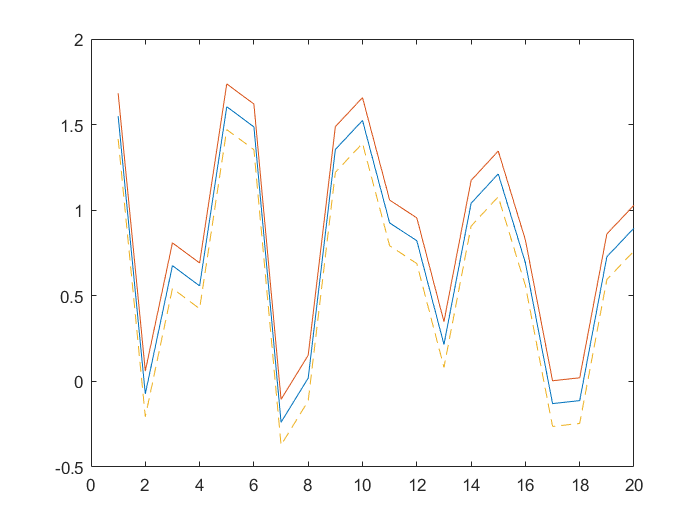


plot(A(1:20,1))
hold on
plot(A(1:20,1)+mean_error,'-')
hold on
plot(A(1:20,1)-mean_error,'--')
hold off

std_error=(var_error)^(1/2)

std_error = 0.0027

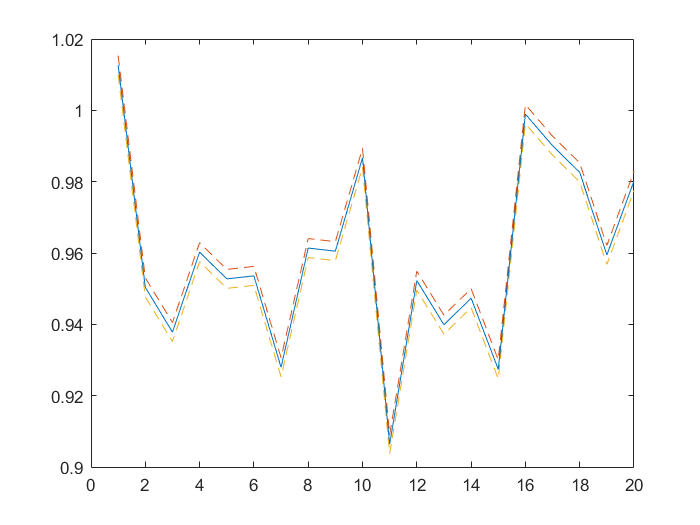

plot(A_hat(1:20,1))
hold on
plot(A_hat(1:20,1)+std_error,'--')
hold on
plot(A_hat(1:20,1)-std_error,'--')
hold off

std_error=(var_error)^(1/2)

std_error = 0.0031

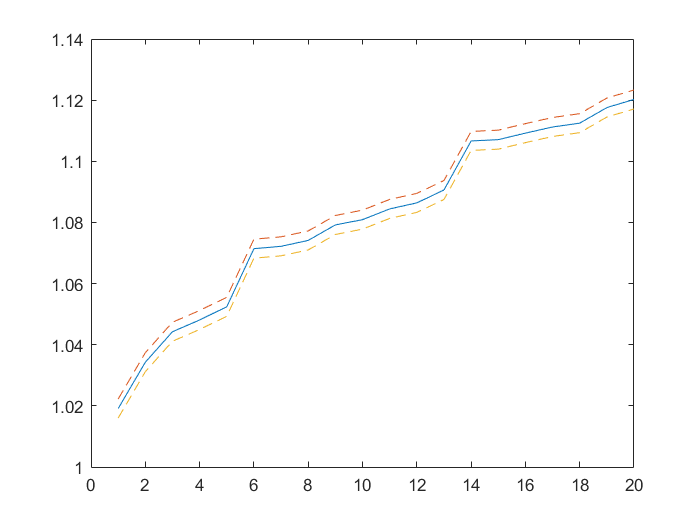

plot(sort(A_hat(1:20,1)))
hold on
plot(sort(A_hat(1:20,1))+std_error,'--')
hold on
plot(sort(A_hat(1:20,1))-std_error,'--')
hold off

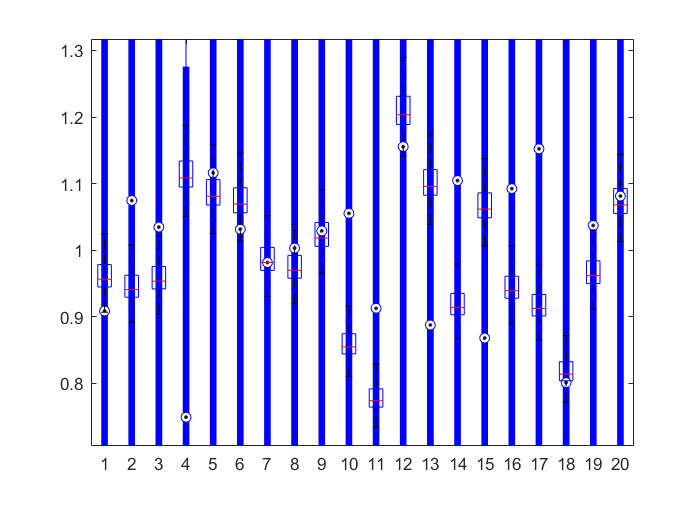

% boxplot(A(1:100,1:20),'PlotStyle','compact');
% hold on
% boxplot(A_hat(1:100,1:20));
% hold off

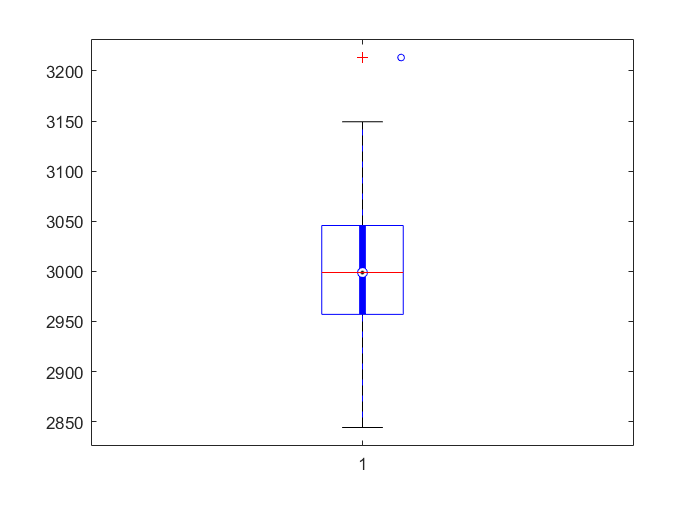

boxplot(Y,'PlotStyle','compact');
hold on
boxplot(y_hat);
hold off

قسمت سوم

Y_hat=A_hat*X;

error=norm(Y-Y_hat)/norm(Y);
disp(["Model error= ",num2str(error)])

    "Model error= "    "2.7967e-16"



قسمت چهارم

e=Y-Y_hat;
sigma2=(e'*e)/(100-1)

sigma2 = 7.1021e-25

norm(N)

ans = 9.7567

قسمت پنجم

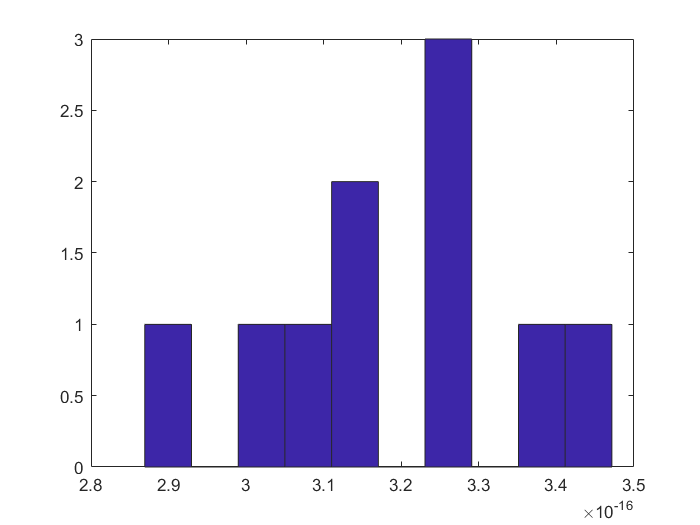

%%iteration=10,N~(0,1)
err=[];
for i=1:10
    n=rand(100,1);
    Y=A*X+n;
    A_hat=Y*pinv(X);
    error_model=norm((Y-A_hat*X))/norm(Y);
    err=[err error_model];
end

hist(err,i);

mean1=mean(err);
var1=var(err);

disp(["mean= ", num2str(mean1)])

    "mean= "    "3.1853e-16"



disp(["var= ", num2str(var1)])

    "var= "    "3.1585e-34"



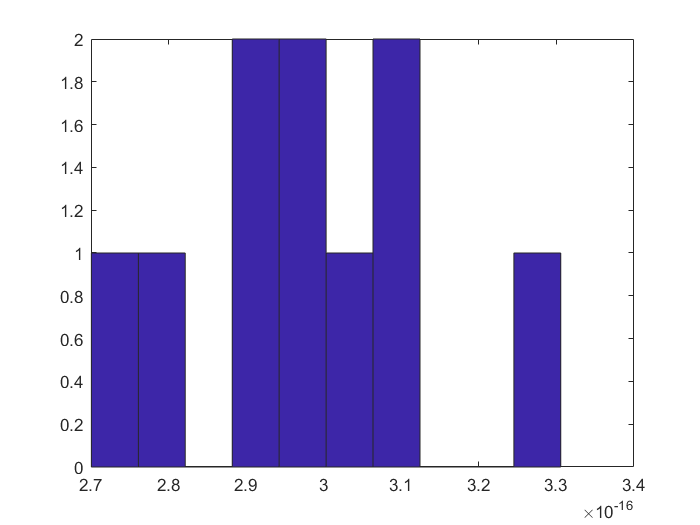


% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 

%%iteration=10,N~(0,0.01)

err=[];
for i=1:10
    n=sqrt(0.01)*rand(100,1);
    Y=A*X+n;
    A_hat=Y*pinv(X);
    error_model=norm((Y-A_hat*X))/norm(Y);
    err=[err error_model];
end

hist(err,i);

mean1=mean(err);
var1=var(err);

disp(["mean= ", num2str(mean1)])

    "mean= "    "2.9847e-16"



disp(["var= ", num2str(var1)])

    "var= "    "2.7085e-34"



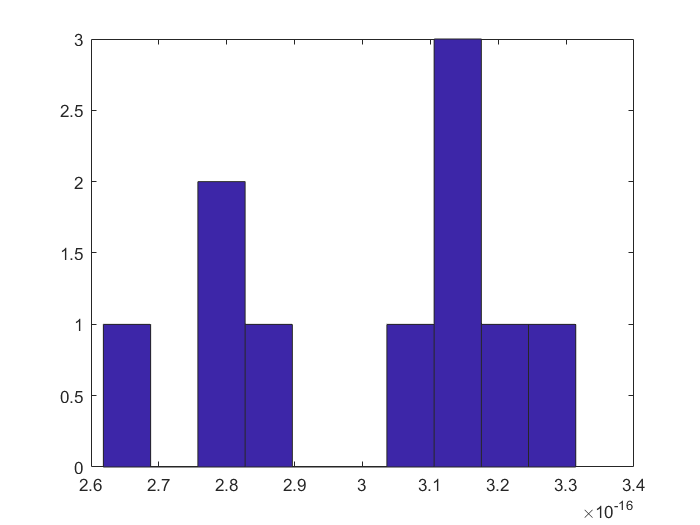


% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 

%%iteration=10,N~(0,100)

err=[];
for i=1:10
    n=sqrt(100)*rand(100,1);
    Y=A*X+n;
    A_hat=Y*pinv(X);
    error_model=norm((Y-A_hat*X))/norm(Y);
    err=[err error_model];
end

hist(err,i);

mean1=mean(err);
var1=var(err);

disp(["mean= ", num2str(mean1)])

    "mean= "    "3.0043e-16"



disp(["var= ", num2str(var1)])

    "var= "    "5.035e-34"



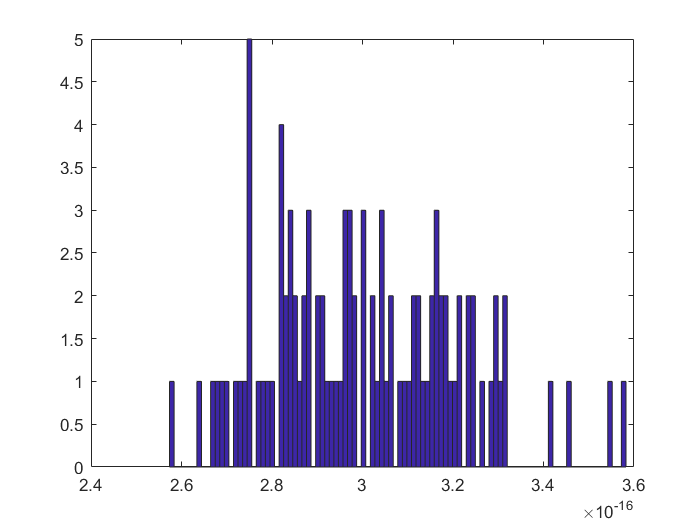

%%iteration=100,N~(0,1)
err=[];
for i=1:100
    n=rand(100,1);
    Y=A*X+n;
    A_hat=Y*pinv(X);
    error_model=norm((Y-A_hat*X))/norm(Y);
    err=[err error_model];
end

hist(err,i);

mean1=mean(err);
var1=var(err);

disp(["mean= ", num2str(mean1)])

    "mean= "    "3.0039e-16"



disp(["var= ", num2str(var1)])

    "var= "    "4.3494e-34"



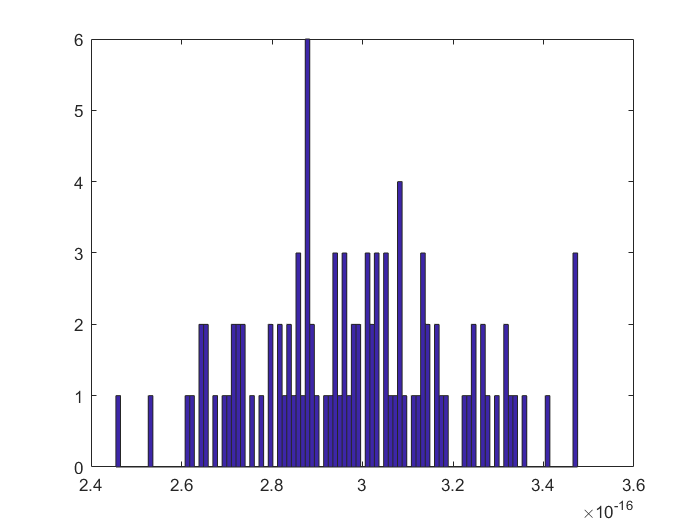


% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 
%%iteration=100,N~(0,0.01)

err=[];
for i=1:100
    n=sqrt(0.01)*rand(100,1);
    Y=A*X+n;
    A_hat=Y*pinv(X);
    error_model=norm((Y-A_hat*X))/norm(Y);
    err=[err error_model];
end

hist(err,i);

mean1=mean(err);
var1=var(err);

disp(["mean= ", num2str(mean1)])

    "mean= "    "2.9816e-16"



disp(["var= ", num2str(var1)])

    "var= "    "4.8862e-34"



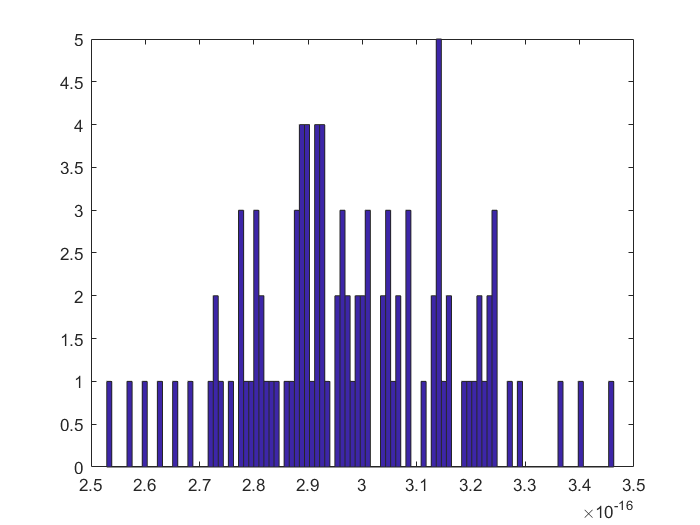


% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 
%%iteration=100,N~(0,100)

err=[];
for i=1:100
    n=sqrt(100)*rand(100,1);
    Y=A*X+n;
    A_hat=Y*pinv(X);
    error_model=norm((Y-A_hat*X))/norm(Y);
    err=[err error_model];
end

hist(err,i);

mean1=mean(err);
var1=var(err);

disp(["mean= ", num2str(mean1)])

    "mean= "    "2.977e-16"



disp(["var= ", num2str(var1)])

    "var= "    "3.4847e-34"



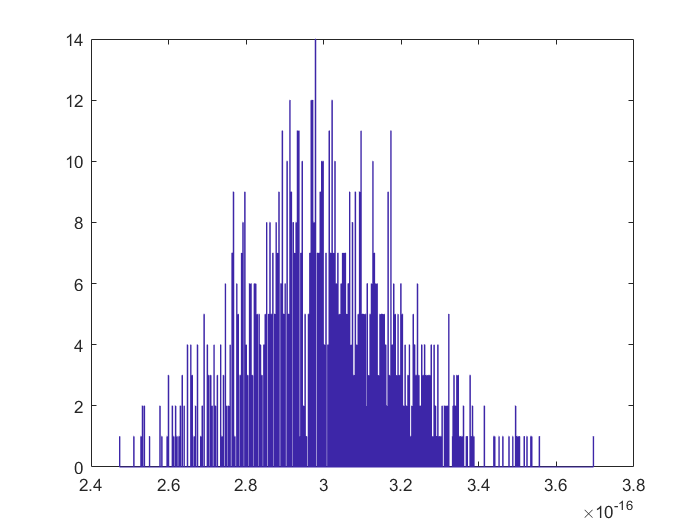

%%iteration=1000,N~(0,1)
err=[];
for i=1:1000
    n=rand(100,1);
    Y=A*X+n;
    A_hat=Y*pinv(X);
    error_model=norm((Y-A_hat*X))/norm(Y);
    err=[err error_model];
end

hist(err,i);

mean1=mean(err);
var1=var(err);

disp(["mean= ", num2str(mean1)])

    "mean= "    "3.0022e-16"



disp(["var= ", num2str(var1)])

    "var= "    "3.6766e-34"



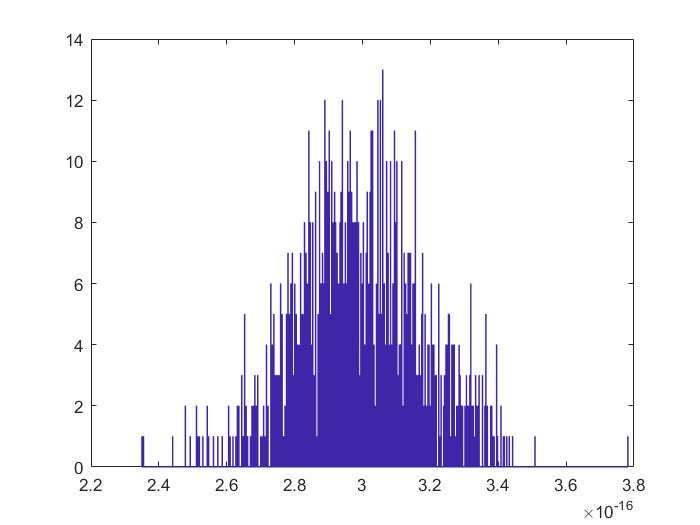


% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 
%%iteration=1000,N~(0,0.01)

err=[];
for i=1:1000
    n=sqrt(0.01)*rand(100,1);
    Y=A*X+n;
    A_hat=Y*pinv(X);
    error_model=norm((Y-A_hat*X))/norm(Y);
    err=[err error_model];
end

hist(err,i);

mean1=mean(err);
var1=var(err);

disp(["mean= ", num2str(mean1)])

    "mean= "    "2.9991e-16"



disp(["var= ", num2str(var1)])

    "var= "    "3.5445e-34"



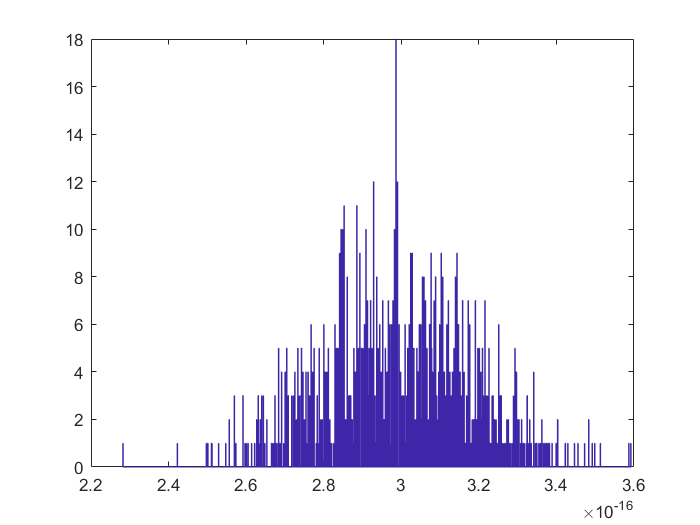



% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 
%%iteration=1000,N~(0,100)

err=[];
for i=1:1000
    n=sqrt(100)*rand(100,1);
    Y=A*X+n;
    A_hat=Y*pinv(X);
    error_model=norm((Y-A_hat*X))/norm(Y);
    err=[err error_model];
end

hist(err,1000);

mean1=mean(err);
var1=var(err);

disp(["mean= ", num2str(mean1)])

    "mean= "    "2.9967e-16"



disp(["var= ", num2str(var1)])

    "var= "    "3.5931e-34"



قسمت ششم


s=rng;
X1=hilb(1000);
A = 1 + sqrt(0.6)*randn(100,1000);
N = randn(100,1);
rng(s);
Y=A*X+N;
% % % fist part
%%%%%%%%%%%%%
A_hat1=Y*pinv(X);
err1=norm(A-A_hat1,2)/norm(A,2);
disp(["Fist error (A-A_hat) for old X = ",num2str(err1)])
%%%%%%%%%%%%%
Y1=A*X1+N;
A_hat2=Y1*pinv(X1);
err2=norm(A-A_hat2,2)/norm(A,2);
disp(["Second error (A-A_hat) for new X= ",num2str(err2)])
%%%%%%%%%%%%%
alfa=0.1;
A_hat3=Y*(X'*(X*X'+alfa*eye(1000))^-1);
err3=norm(A-A_hat3,2)/norm(A,2);
disp(["Third error (A-A_hat) for alfa method= ",num2str(err3)])

% % % second part
%%%%%%%%%%%%%
A_hat1=Y*pinv(X);
Y_hat11=A_hat1*X;
er1=norm(Y-Y_hat11)/norm(Y,2);
disp(["Fist error (Y-Y_hat) for old X = ",num2str(er1)])
%%%%%%%%%%%%%
Y1=A*X1+N;
A_hat7=Y1*pinv(X1);
Y_hat5=A_hat7*X;
er2=norm(Y1-Y_hat5)/norm(Y1,2);
disp(["Second error (Y-Y_hat) for new X= ",num2str(er2)])
%%%%%%%%%%%%%
alfa=0.1;
A_hat33=Y*(X'*(X*X'+alfa*eye(1000))^-1);
Y_hat33=A_hat33*X1;
er3=norm(Y1-Y_hat33,2)/norm(Y1,2);
disp(["Third error (Y-Y_hat) for alfa method= ",num2str(er3)])

s=rng;
X1=hilb(1000);
A = 1 + sqrt(0.6)*randn(100,1000);
N = randn(100,1);
rng(s);
Y=A*X1(1:1000,1)+N;
A_hat22=Y*pinv(X);
ErrEstimate1 = norm(A-A_hat22,2)/norm(A,2);

% Display the error
disp(['Error between A and A_hat (Error of the estimation): ', num2str(ErrEstimate1)]);

y_hat5=A_hat22*X1(1:1000,1);
er=norm(Y-y_hat5)/norm(Y);
disp(["Model error= ",num2str(er)])

part 2

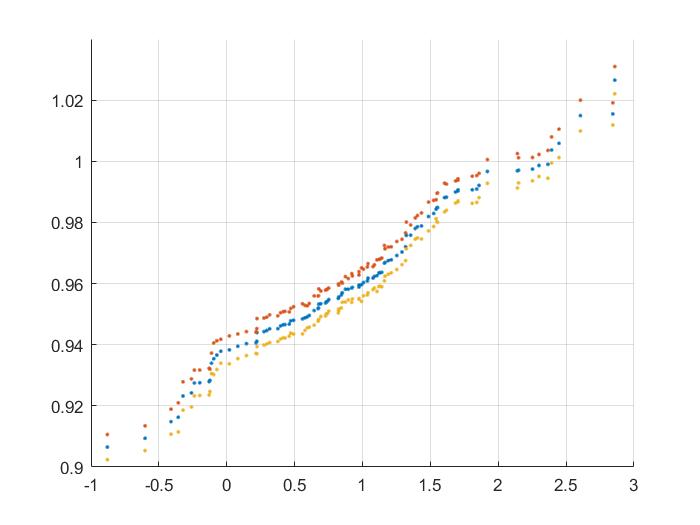

cov_A_hat=((errors'*errors)*(X'*X)^-1)/(100-1);
errbar=sqrt(diag(X*cov_A_hat*X'));
u=X(1:100,1);

figure;
scatter(sort(A(1:100,1)),sort(A_hat(1:100,1)),'.');
hold on
scatter(sort(A(1:100,1)),sort(A_hat(1:100,1))+errbar(1:100,1),'.');
hold on
scatter(sort(A(1:100,1)),sort(A_hat(1:100,1))-errbar(1:100,1),'.');
grid
hold off

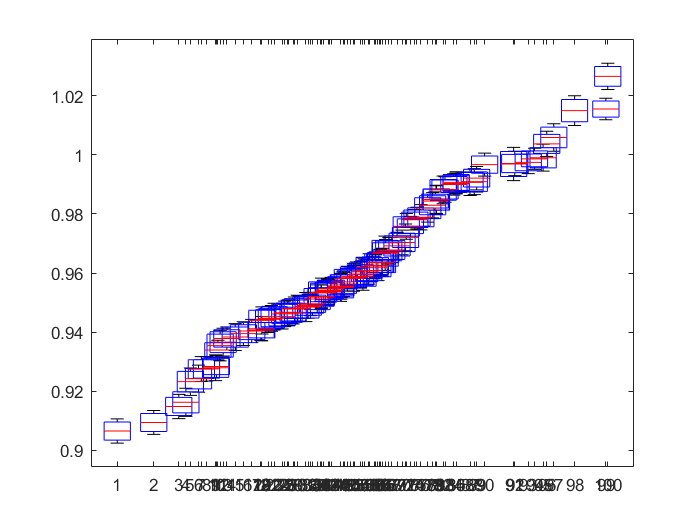

x=sort(A(1:100,1)).';
y=sort(A_hat(1:100,1)).';
data = [(sort(A_hat(1:100,1))-errbar(1:100,1)).'; sort(A_hat(1:100,1)).'; (sort(A_hat(1:100,1))+errbar(1:100,1)).'];
yneg=errors.';

% Add a box plot
boxplot(data, 'positions', x, 'widths', 0.2);

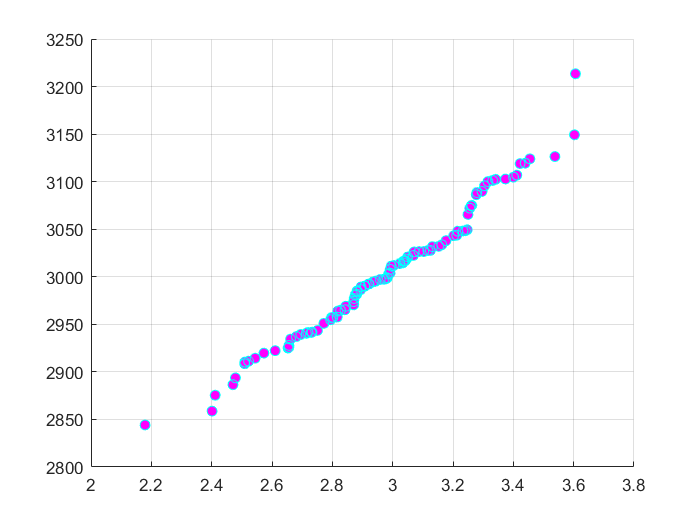

cov_A_hat=((errors'*errors)*(X'*X)^-1)/(100-1);
errbar=sqrt(diag(X*cov_A_hat*X'));
u=X(1:100,1);

figure;
scatter(sort(u),sort(y_hat),'green','.');
hold on
scatter(sort(u),sort(y_hat)+errbar(1:100,1),'magenta','filled');
hold on
scatter(sort(u),sort(y_hat)-errbar(1:100,1),'cyan');
grid
hold off

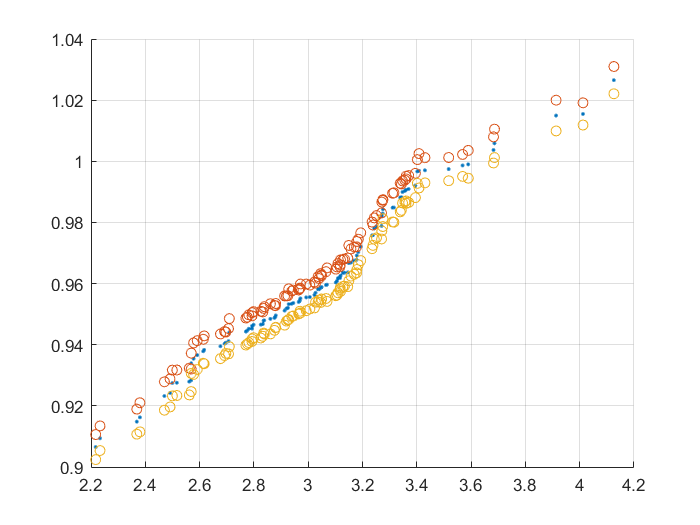

cov_A_hat=((errors'*errors)*(X'*X)^-1)/(100-1);
errbar=sqrt(diag(X*cov_A_hat*X'));
u=X(1:100,1);

figure;
scatter(sort(u),sort(y_hat),'.');
hold on
scatter(sort(u),sort(y_hat)+errbar(1:100,1));
hold on
scatter(sort(u),sort(y_hat)-errbar(1:100,1));
grid
hold off

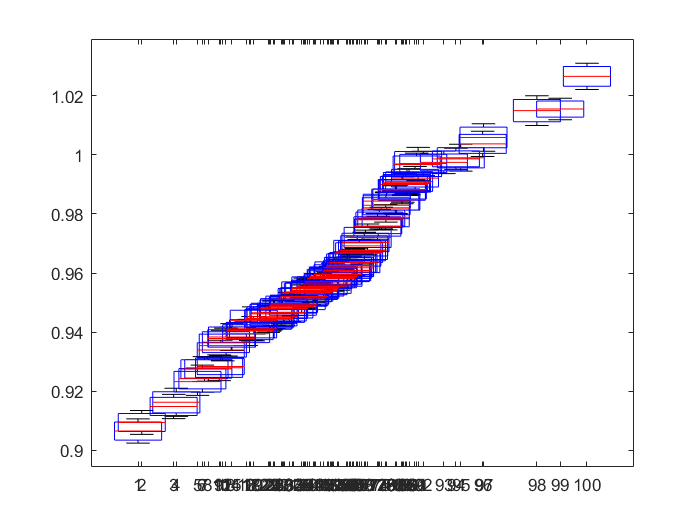

x=sort(u).';
y=sort(y_hat).';
data = [(sort(y_hat)-errbar(1:100,1)).'; sort(y_hat).'; (sort(y_hat)+errbar(1:100,1)).'];
yneg=errors.';

% Add a box plot
boxplot(data, 'positions', x, 'widths', 0.2);

x=sort(A(1:100,1)).';
y=sort(A_hat(1:100,1)).';
data = [(sort(A_hat(1:100,1))-errbar(1:100,1)).'; sort(A_hat(1:100,1)).'; (sort(A_hat(1:100,1))+errbar(1:100,1)).'];
yneg=errors.';

% Add a box plot
boxplot(data, 'positions', x, 'widths', 0.2);

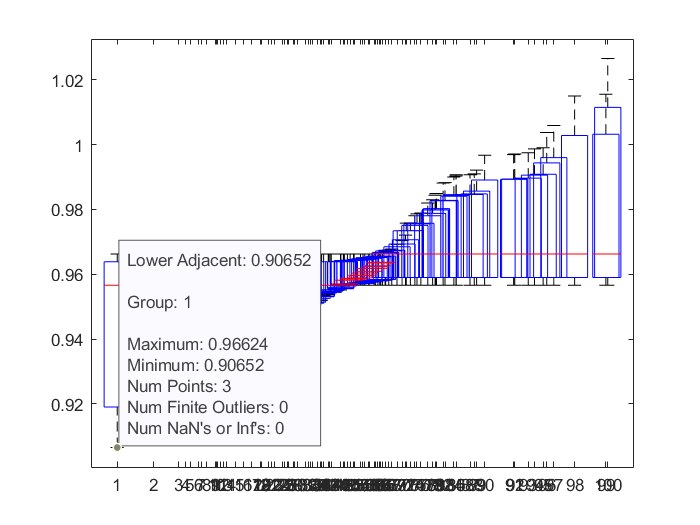

% 
% x = sort(A(1:100,1)).';
% y = sort(A_hat(1:100,1)).';
% mean_y = mean(y);
% std_y = std(y);
% 
% % 95% confidence interval
% %  confidence interval
% alpha = 0.05;  
% n = length(y);
% t = tinv(1-alpha/2, n-1);
% ci = t * std_y / sqrt(n);
% lower_bound = mean_y - ci;
% upper_bound = mean_y + ci;
% 
% % box plot
% data = [y; lower_bound * ones(1, length(y)); upper_bound * ones(1, length(y))];
% yneg = errors.';
% 
% 
% boxplot(data, 'positions', x, 'widths', 0.2);

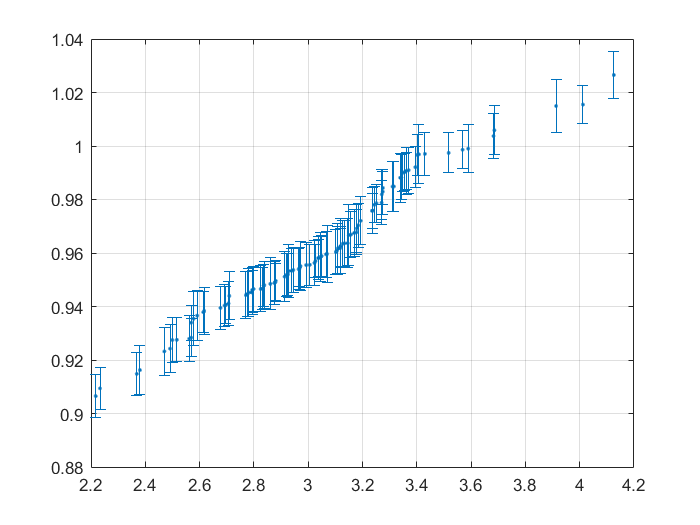

% the covariance matrix 
cov_A_hat = ((errors' * errors) * (X' * X)^-1) / (100 - 1);
se = sqrt(diag(X * cov_A_hat * X'));

% confidence interval
alpha = 0.05;
z = norminv(1 - alpha/2);
ci = z * se;

%plot
u_sorted = sort(u);
y_hat_sorted = sort(y_hat);
errbar_sorted = sort(errbar);

figure;
errorbar(u_sorted, y_hat_sorted, ci(1:100,:), '.');
grid on;